# Playing with vectors

Vectors are the most essential mathematical objects in Anakin. The class `vector` allows creating them. 

Start by importing the Anakin framework into Matlab. Be sure to include Anakin's base directory before you run this line:

import anakin.*

## Object creation

The default vector is the null vector:

v = vector % default call

v = Vector with canonical components:
     0
     0
     0


Numerical vectors can be created by passing their canonical components individually or as an array:

a = vector(1,2,3) % individual canonical componentes

a = Vector with canonical components:
     1
     2
     3


b = vector([4;5;6]) % as a column vector

b = Vector with canonical components:
     4
     5
     6


c = vector([7,8,9]) % as a row vector

c = Vector with canonical components:
     7
     8
     9


The components that define the vector can be given in another basis. Internally, the vector object stores only its components in the canonical vector basis:

B1 = basis([1;0;0],[0;cos(pi/6);sin(pi/6)],[0;-sin(pi/6);cos(pi/6)]);
b = vector([0;1;0],B1) % this is the j vector of B1

b = Vector with canonical components:
         0
    0.8660
    0.5000


For convenience, any object of vector class or a subclass can be passed as input. The result is converted to class vector:

A = point; % a point object, subclass of vector
a = vector(A); % converted to vector

## Basic functionality

To obtain the components of an existing vector in a given basis, use the `components` method:

b.components % returns an array with the components of b in canonical vector basis

ans =          0
    0.8660
    0.5000


b.components(B1) % returns an array with the components of b in B1

ans =      0
     1
     0


Single components of a vector can be extracted with methods `x`, `y`, `z`. A basis can also be indicated as above:

b.y % y component of b in the canonical vector basis

ans = 0.8660

b.y(B1) % y component of b in B1

ans = 1

Vectors can be added, compared for equality, dotted, crossed, etc, and there are other useful methods that can be used:

a = vector([1;2;0])

a = Vector with canonical components:
     1
     2
     0


b = vector([2;2;0])

b = Vector with canonical components:
     2
     2
     0



c = a + b % sum vector

c = Vector with canonical components:
     3
     4
     0


2*a % two times a

ans = Vector with canonical components:
     2
     4
     0


d = a - b % difference vector

d = Vector with canonical components:
    -1
     0
     0


dot(a,b) % dot product

ans = 6

e = cross(a,b) % cross product

e = Vector with canonical components:
     0
     0
    -2


T = tensorproduct(a,b) % tensor product

T = Tensor with canonical components:
     2     2     0
     4     4     0
     0     0     0



a == b % compare two vectors

ans = logical
   0


a ~= b

ans = logical
   1



norm(a) % norm of a vector (also accessible as magnitude(a))

ans = 2.2361

u = dir(a) % returns a unitary vector in the same direaction as a

u = Vector with canonical components:
    0.4472
    0.8944
         0



isunitary(a) % returns true if the vector is unitary (this is false)

ans = logical
   0


isperpendicular(a,b) % returns true if the two vectors are perpendicular (this is false)

ans = logical
   0


isparallel(a,2*a) % returns true if the two vectors are parallel (this is true)

ans = logical
   1


Finally, a numeric vector can be plotted using `plot`:

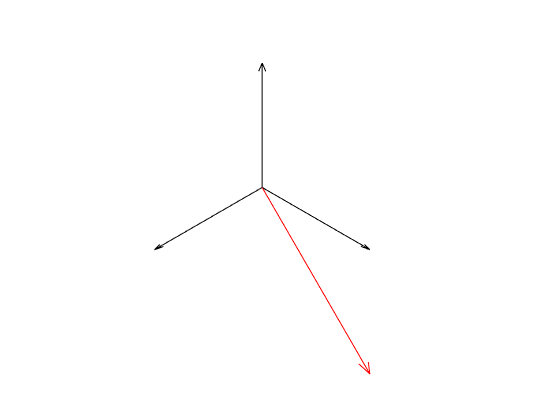

ax = axes('DataAspectRatio',[1,1,1]);
ax.XAxis.Visible = 'off';
ax.YAxis.Visible = 'off';
ax.ZAxis.Visible = 'off';
view([1,1,1]);

basis().plot; % plot the basis for reference

a = vector([1;2;0]);
a.plot('color','r'); % pass quiver3 plotting arguments to change color, style, etc.

## Symbolic vectors

Vectors with symbolic components have additional functionality (running this requires the Symbolic Math Toolbox installed):

syms t theta(t) phi(t); % declare symbolic variables
assume([in(t, 'real'), in(theta(t), 'real'), in(phi(t), 'real')]); 

a = vector(cos(theta),sin(theta),0) % a rotating vector

a = Vector with canonical components:
 cos(theta(t))
 sin(theta(t))
             0
 

One may compute the time derivative of a symbolic vector with respect to a chosen reference frame with method `dt`. The result is also a vector. If no reference frame is provided, the canonical one is assumed:

a.dt % time derivative of a in the canonical reference frame

ans = Vector with canonical components:
 -sin(theta(t))*diff(theta(t), t)
  cos(theta(t))*diff(theta(t), t)
                                0
 


b = vector(1,2,3);

O = point(0,0,0);
B1 = basis([1;0;0],[0;cos(phi);sin(phi)],[0;-sin(phi);cos(phi)]);
S1 = frame(O,B1);

b.dt(S1) % time derivative of b in S1

ans = Vector with canonical components:
                  0
  3*diff(phi(t), t)
 -2*diff(phi(t), t)
 

To particularize a symbolic vector at particular values of its degrees of freedom, one may use `subs`, by specifying them in a list:

a.subs({theta},{pi/6}) % replace theta with pi/6

ans = Vector with canonical components:
    0.8660
    0.5000
         0
